%"Dispatcher" by Kambadur Ananthamurthy
% This code uses actual dfbf curves from my data and analyses it for time
% cells using multiple methods
% Currently this is being tested for single session data. I will test with a
% batch, soon.

tic
clear
close all

## Addpaths


addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))
addpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth/localCopies')


## Dataset details

make_db
ops0.fig                       = 1;
ops0.saveData                  = 1;
ops0.onlyProbeTrials           = 0;
ops0.loadSyntheticData         = 1;
ops0.doSigOnly                 = 0;

% Methods - 0: Don't run; 1: Run
runMethodA  = 0; 
runMethodB  = 0;
runMethodC  = 0;
runMethodD  = 0;
runMethodE  = 1;

if ops0.loadSyntheticData
    setupSyntheticDataParameters
end

## Figure details

if ops0.fig
    figureDetails = compileFigureDetails(20, 2, 10, 0.5, 'jet'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
end

## Main script

fprintf('Analyzing %s_%i_%i - Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Analyzing M26_5_4 - Date: 20180514


saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

%for i = 1:length(sdcp)
%i = 1;
i = length(sdcp);
if ops0.loadSyntheticData
    load([saveFolder ...
        'synthDATA' ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' num2str(sdcp(i).eventAmplificationFactor) ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '.mat']);
    myData.dfbf = sdo.syntheticDATA;
    myData.dfbf_2D = sdo.syntheticDATA_2D;
    myData.baselines = zeros(size(sdo.syntheticDATA)); %initialization
else
    %Load processed data (processed dfbf for dataset/session)
    myData = load([saveFolder db.mouseName '_' db.date '.mat']);
end
trialDetails = getTrialDetails(db);

Getting trial details ...
... done!


%Significant-Only Traces
if ops0.doSigOnly
    if ops0.onlyProbeTrials
        disp('Only analysing Probe Trials ...')
        dfbf_sigOnly = findSigOnly(myData.dfbf(:, iProbeTrials, :));
    else
        dfbf_sigOnly = findSigOnly(myData.dfbf);
    end
    DATA = dfbf_sigOnly;
else
    DATA = myData.dfbf;
end

## Analysis Pipeline: Method A - Mehrab's Reliability Analysis (Bhalla Lab)

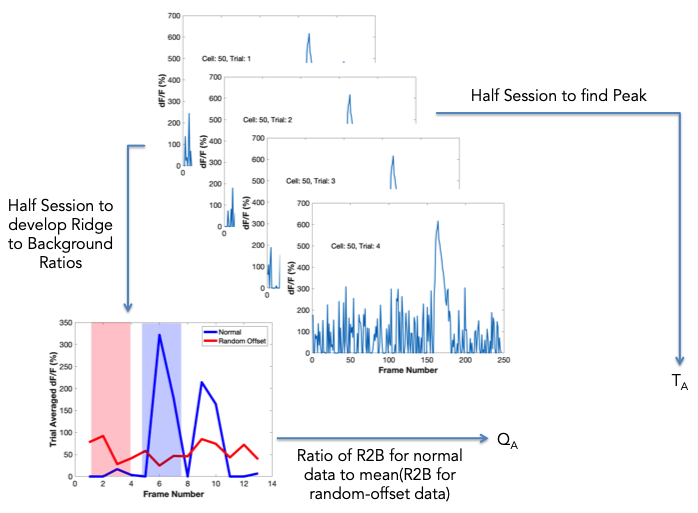

if runMethodA
    mAInput.cellList = 1:1:size(DATA,1); %using all cells
    mAInput.onFrame = sdcp.startFrame;
    mAInput.offFrame = sdcp.endFrame;
    mAInput.ridgeHalfWidth = 100; %in ms
    mAInput.nIterations = 5000; %number of iterations of randomisation used to find averaged r-shifted rb ratio - might have to go as high as 3000.
    mAInput.selectNonOverlappingTrials = 1; %1 - non-overlapping trial sets used for kernel estimation and rb ratio calculation, 0 - all trials used for both
    mAInput.earlyOnly = 0; %0 - uses all trials; 1 - uses only the first 5 trials of the session
    mAInput.startTrial = 1; %the analysis begins with this trial number (e.g. - 1: analysis on all trials)
    
    [mAOutput] = runMehrabR2BAnalysis(DATA, mAInput, trialDetails);
    mAOutput.normQ = (mAOutput.Q) ./max(mAOutput.Q(~isinf(mAOutput.Q)));
    
    save([saveFolder db.mouseName '_' db.date '_methodA.mat' ], 'mAInput', 'mAOutput')
    fig1 = figure(1);
    set(fig1,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mAOutput.Q, 'g*')
    title('Mehrab | Quality A', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('R2Bnormal/Mean R2Brandom', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot(mAOutput.T/db.samplingRate, 'g*')
    ylim([0 (db.nFrames/db.samplingRate)])
    %ylim([(mAInput.onFrame-10)/db.samplingRate (mAInput.offFrame + 10)/db.samplingRate])
    title('Mehrab | Time A', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline: Method B - William Mau's Temporal Information (Eichenbaum Lab)

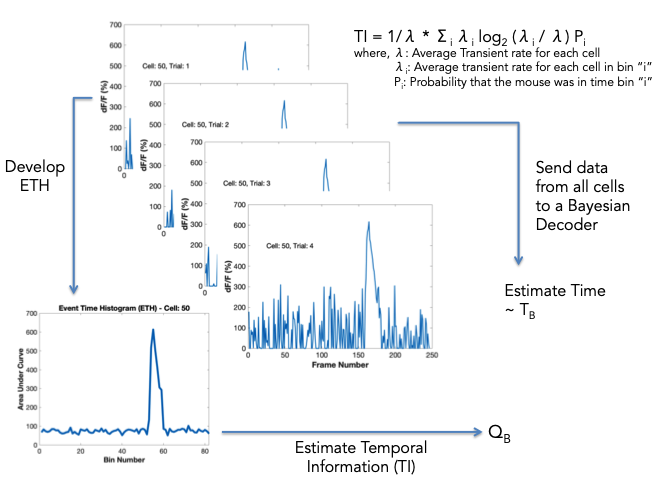

if runMethodB
    mBInput.delta = 3;
    mBInput.whichTrials = 'alternate';
    mBInput.labelShuffle = 'off';
    mBInput.distribution4Bayes = 'mvmn';
    [mBOutput] = runWilliamTIAnalysis(DATA, mBInput);
    mBOutput.normQ = (mBOutput.Q) ./max(mBOutput.Q);
    
    save([saveFolder db.mouseName '_' db.date '_methodB.mat' ], 'mBInput', 'mBOutput')
    
    fig2 = figure(2);
    set(fig2,'Position',[300, 300, 1000, 500])
    clf
    subplot(2, 3, 2)
    plot(mBOutput.Q, 'b*')
    title('William | Quality B' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('TI (bits/spike)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(2, 3, 4)
    imagesc(mBOutput.Yfit_actual_2D)
    colormap('jet')
    z = colorbar;
    ylabel(z,'Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    title('Ground Truth', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('All Frames', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Trial Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(2, 3, 5)
    imagesc(mBOutput.Yfit_2D)
    z = colorbar;
    ylabel(z,'Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    title('Prediction', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('All Frames', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Trial Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(2, 3, 6)
    imagesc(mBOutput.YfitDiff_2D)
    z = colorbar;
    ylabel(z,'Difference in Frame Numbers', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    title('Error', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('All Frames', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Trial Frame Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline: Method C - Simple Analysis

Method C1

if runMethodC
    mCInput.delta = 3;
    mCInput.skipFrames = [];
    mCInput.trialThreshold = 25; % in %
    [mCOutput] = runSimpleTCAnalysis(DATA, mCInput);
    mCOutput.normQ1 = (mCOutput.Q1) ./max(mCOutput.Q1);
    mCOutput.normQ2 = (mCOutput.Q2) ./max(mCOutput.Q2);
    
    save([saveFolder db.mouseName '_' db.date '_methodC.mat' ], 'mCInput', 'mCOutput')
    fig3 = figure(3);
    set(fig3,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mCOutput.Q1, 'r*')
    title('Simple | Quality C1' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Hit Trial Ratio * ksstat', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'r*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time C', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

Method C2

if runMethodC
    fig4 = figure(4);
    set(fig4,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mCOutput.Q2, 'k*')
    %ylim([0 10])
    title('Simple | Quality C2' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Mean/Std [Timed]', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'k*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time C', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Analysis Pipeline: Method D - Sequence based analysis

if runMethodD
    mDInput.delta = 3;
    mDInput.skipFrames = [];
    mDInput.gaussianSmoothing = 1; %logical
    mDInput.nSamples = 5; %for Gaussian Kernel
    mDInput.automatic = 1; %for selecting P; logical
    mDInput.timeVector = (1:db.nFrames*size(DATA,2)) * (1/db.samplingRate); %in seconds; %For derivative
    [mDOutput] = runSeqBasedTCAnalysis(DATA, mDInput);
    mDOutput.normQ = (mDOutput.Q) ./max(mDOutput.Q);
   
    fig5 = figure(5);
    set(fig5,'Position',[300, 300, 1000, 300])
    clf
    subplot(1, 2, 1)
    plot(mDOutput.Q, 'm*')
    title('Arnaud | Quality D' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Cross Correlation with PC', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
    
    subplot(1, 2, 2)
    plot((mDOutput.T * mDInput.delta)/db.samplingRate, 'm*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time D', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

## Analysis Pipeline E - Support Vector Machine based Classification

Label Shuffle Control: off
Now, developing ETH for 135 cells ...
... 10 cells analysed ...
... 20 cells analysed ...
... 30 cells analysed ...
... 40 cells analysed ...
... 50 cells analysed ...
... 60 cells analysed ...
... 70 cells analysed ...
... 80 cells analysed ...
... 90 cells analysed ...
... 100 cells analysed ...
... 110 cells analysed ...
... 120 cells analysed ...
... 130 cells analysed ...
... done!


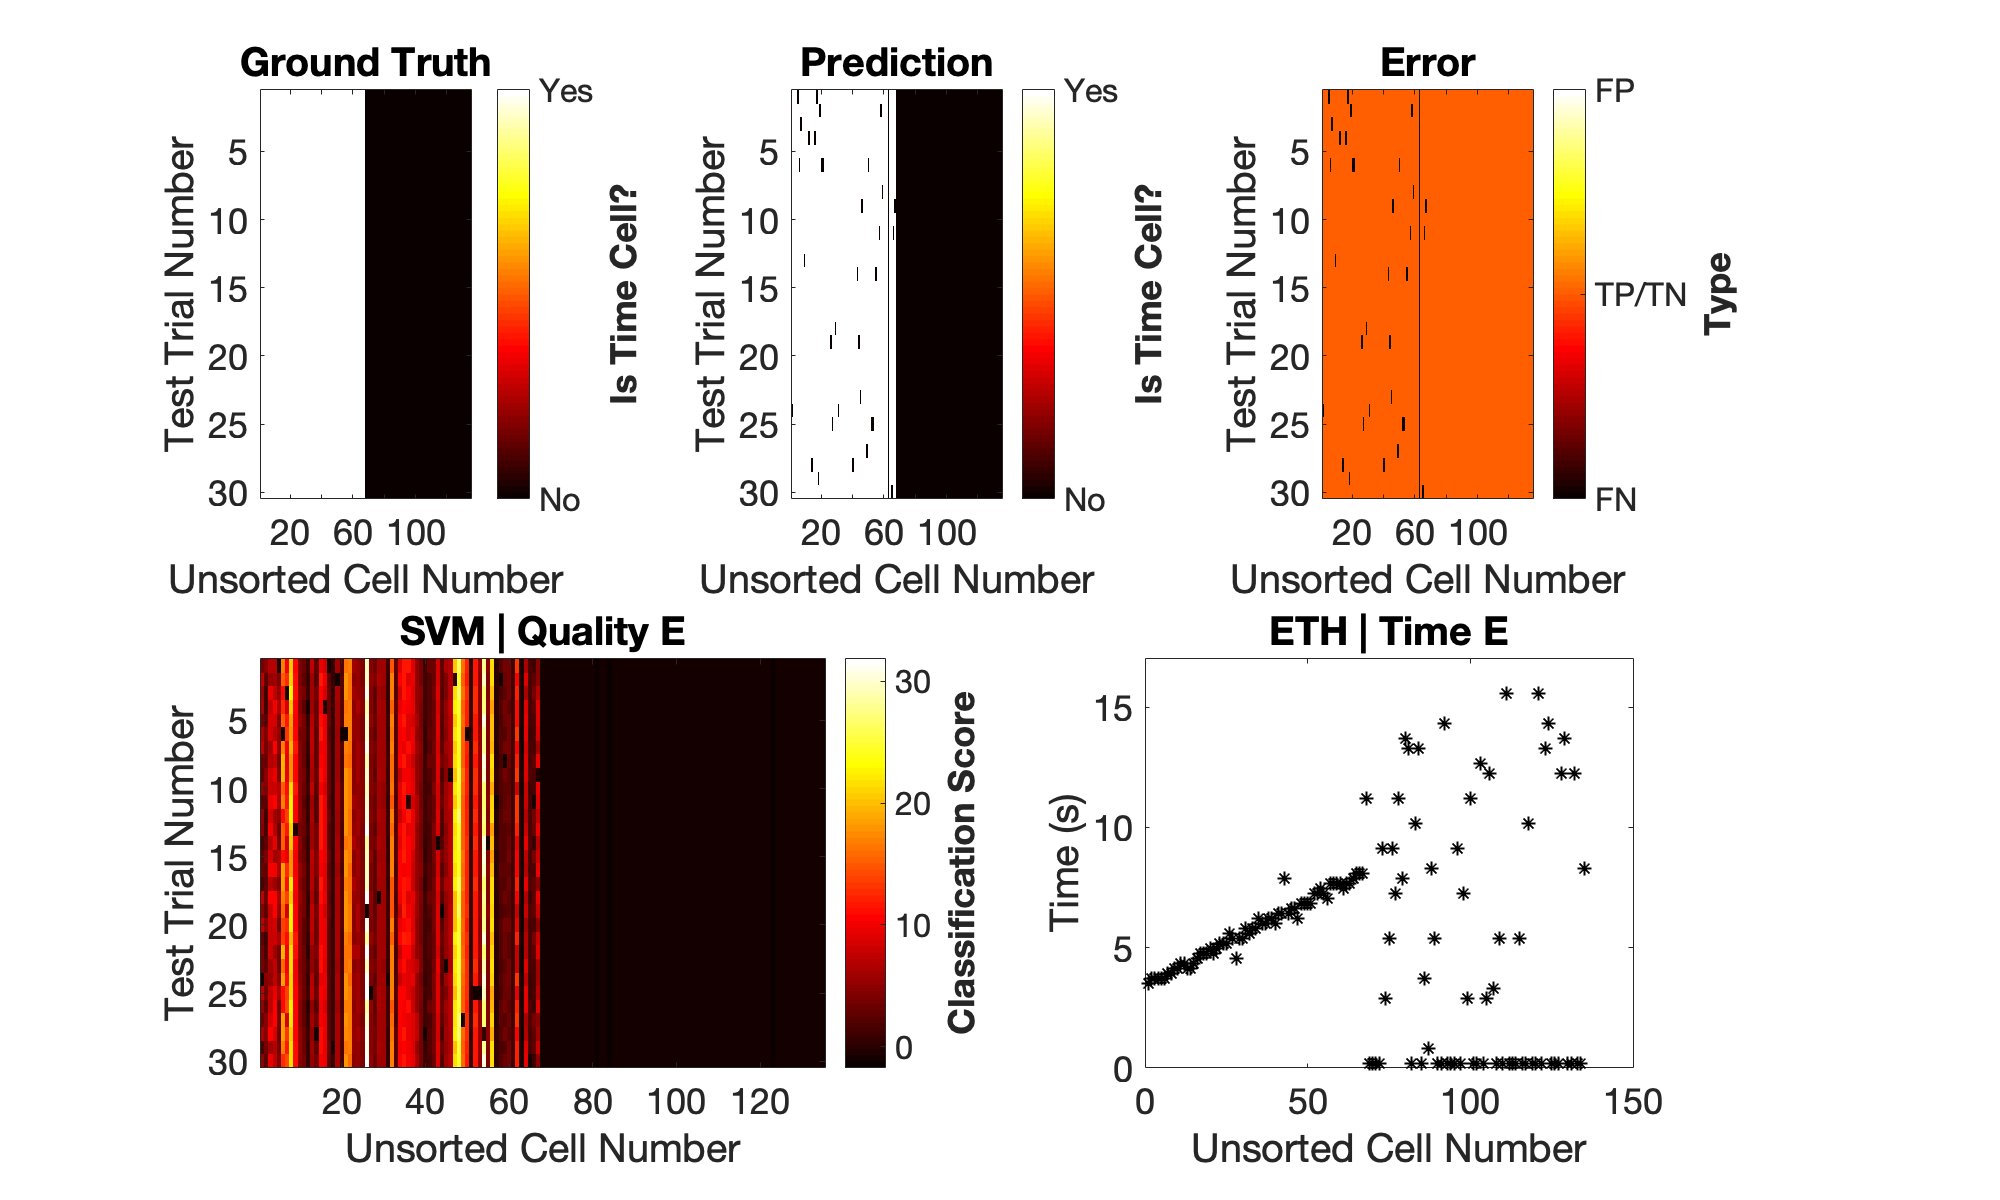

if runMethodE
    mEInput.delta = 3;
    mEInput.skipFrames = [];
    mEInput.gaussianSmoothing = 0; %logical
    mEInput.nSamples = 5; %for Gaussian Kernel; relevant only if gaussian smoothing is on
    mEInput.whichTrials = 'alternate';
    mEInput.labelShuffle = 'off';
    if ops0.loadSyntheticData
        mEInput.ptcList = sdo.ptcList;
        mEInput.ocList = sdo.ocList;
    else
        if strcmpi(mEInput.whichCells, 'timeCells')
            mEInput.ptcList = input('Enter Time Cell List: ');
        elseif strcmpi(mEInput.whichCells, 'otherCells')
            mEInput.ocList = input('Enter Other Cell List: ');
        end
    end
    
    [mEOutput] = runSVMClassification(DATA, mEInput);

    fig6 = figure(6);
    set(fig6,'Position',[300, 300, 1000, 600])
    clf
    subplot(2, 9, 1:2)
    imagesc(mEOutput.Yfit_actual_2D)
    colormap('hot')
    z = colorbar('XTickLabel',{'No', 'Yes'}, ...
               'XTick', 0:1:1);
    ylabel(z,'Is Time Cell?', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([0 1])
    title('Ground Truth', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 4:5)
    imagesc(mEOutput.Yfit_2D)
    z = colorbar('XTickLabel',{'No', 'Yes'}, ...
               'XTick', 0:1:1);
    ylabel(z,'Is Time Cell?', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([0 1])
    title('Prediction', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 7:8)
    imagesc(mEOutput.YfitDiff_2D)
    z = colorbar('XTickLabel',{'FN', 'TP/TN', 'FP'}, ...
               'XTick', -1:1:1);
    ylabel(z,'Type', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([-1 1])
    title('Error', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 10:13)
    imagesc(mEOutput.Q_2D)
    z = colorbar;
    ylabel(z,'Classification Score', ...
        'FontSize', figureDetails.fontSize-2, ...
        'FontWeight', 'bold')
    caxis([min(min(mEOutput.Q_2D)), max(max(mEOutput.Q_2D))])
    title('SVM | Quality E' , ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Test Trial Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    subplot(2, 9, 15:17)
    plot((mEOutput.T * mEInput.delta)/db.samplingRate, 'k*')
    ylim([0 (db.nFrames/db.samplingRate)])
    title('ETH | Time E', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Unsorted Cell Number', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    ylabel('Time (s)', ...
        'FontSize', figureDetails.fontSize,...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-2)
    
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodE_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodE_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end

## Second Order Stats to compare the outputs

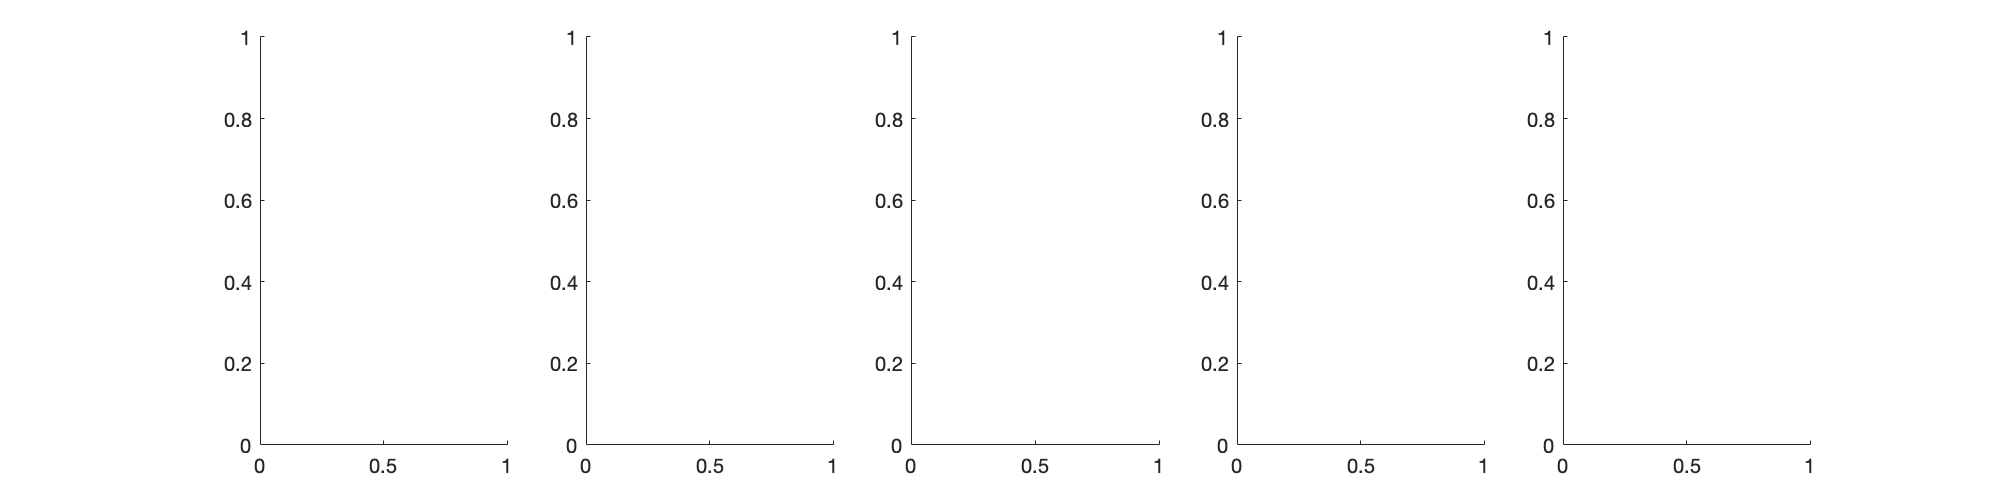

normalize = 0;
fig7 = figure(7);
set(fig7,'Position',[300,300,1000,250])
clf
subplot(1, 5, 1)
if runMethodA
    if normalize
        scatter(sdo.Q, mAOutput.normQ, 'g');
        ylabel('Norm R2Bdata/mean(R2Brand)', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    else
        scatter(sdo.Q, mAOutput.Q, 'g');
        ylabel('R2Bdata/mean(R2Brand)', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    title('Method A', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Quality (Q)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 2)
if runMethodB
    if normalize
        scatter(sdo.Q, mBOutput.normQ, 'b');
        ylabel('Norm TI', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    else
        scatter(sdo.Q, mBOutput.Q, 'b');
        ylabel('TI', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    title('Method B', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Quality (Q)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 3)
if runMethodC
    if normalize
        scatter(sdo.Q, mCOutput.normQ1, 'r');
        ylabel('Norm HT Ratio*Kurtosis', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    else
        scatter(sdo.Q, mCOutput.Q1, 'r');
        ylabel('HT Ratio * ksstat', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    title('Method C(1)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Quality (Q)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 4)
if runMethodC
    if normalize
        scatter(sdo.Q, mCOutput.normQ2, 'k');
        ylabel('Norm Mean/Std [Timed]', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    else
        scatter(sdo.Q, mCOutput.Q2, 'k');
        ylabel('Mean/Std [Timed]', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    title('Method C(2)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Quality (Q)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 5)
if runMethodD
    if normalize
        scatter(sdo.Q, mDOutput.normQ, 'm');
        ylabel('CC with PC', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    else
        scatter(sdo.Q, mDOutput.Q, 'm');
        ylabel('Mean/Std [Timed]', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
    end
    title('Method D', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Quality (Q)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

if normalize
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_normQScatter_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_normQScatter_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
else
    if ops0.loadSyntheticData
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_QScatter_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
            '-djpeg');
    else
        print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_QScatter_' ...
            db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
            '-djpeg');
    end
end


fig8 = figure(8);
set(fig8,'Position',[300,300,1000,250])
clf
subplot(1, 5, 1)
if runMethodA
    scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, mAOutput.T/db.samplingRate, 'g');
    xlim([0 (db.nFrames/db.samplingRate)])
    ylim([0 (db.nFrames/db.samplingRate)])
    title('Method A', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Time (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    ylabel('Time A (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 2)
if runMethodB
%     scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (mBOutput.T * mBInput.delta)/db.samplingRate, 'b');
%     xlim([0 (db.nFrames/db.samplingRate)])
%     ylim([0 (db.nFrames/db.samplingRate)])
%     title('Method B', ...
%         'FontSize', figureDetails.fontSize, ...
%         'FontWeight', 'bold')
%     xlabel('Time (s)', ...
%         'FontSize', figureDetails.fontSize, ...
%         'FontWeight', 'bold')
%     ylabel('Time B (s)', ...
%         'FontSize', figureDetails.fontSize, ...
%         'FontWeight', 'bold')
%     set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 3)
if runMethodC
    scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (mCOutput.T * mCInput.delta)/db.samplingRate, 'r');
    xlim([0 (db.nFrames/db.samplingRate)])
    ylim([0 (db.nFrames/db.samplingRate)])
    title('Method C', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Time (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    ylabel('Time C (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 4)
if runMethodC
    scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (sdo.T * mCInput.delta)/db.samplingRate, 'k');
    xlim([0 (db.nFrames/db.samplingRate)])
    ylim([0 (db.nFrames/db.samplingRate)])
    title('Time from ETH', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Time (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    ylabel('Derived Time (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

subplot(1, 5, 5)
if runMethodD
    scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (mDOutput.T * mDInput.delta)/db.samplingRate, 'k');
    xlim([0 (db.nFrames/db.samplingRate)])
    ylim([0 (db.nFrames/db.samplingRate)])
    title('Time from ETH', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xlabel('Time (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    ylabel('Derived Time (s)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize-3)
end

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_TScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_TScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

toc

Elapsed time is 31.616040 seconds.


disp('All done!')

All done!
